# Linear Regression with one variable

### Loading the dataset

% Loading the dataset
dataSet = load('ex1data1.txt');
% Storing the values in seperate vectors
x = dataSet(:, 1);
y = dataSet(:, 2);
m = length(x) 

m = 97

### Plotting the data

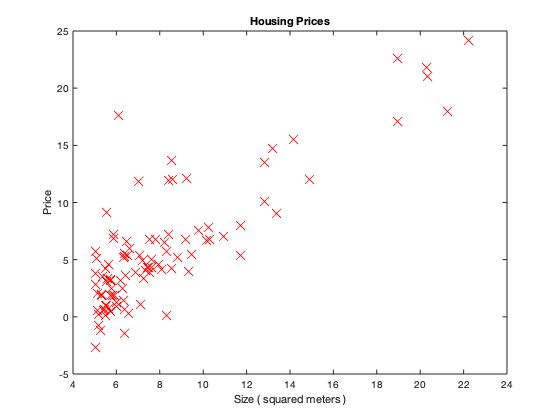

figure;
plot(x, y, 'rx', 'MarkerSize', 10);
xlabel('Size ( squared meters )');
ylabel('Price');
title('Housing Prices');

### Computing the Cost

theta = [0;0];
x=[ones(m,1),x];

% Compute and display initial cost with theta all zeros
computeCost(x, y, theta)

ans = 32.0727


% Compute and display initial cost with non-zero theta
computeCost(x, y,[-1;2])

ans = 54.2425

### Gradient Descent

alpha = 0.01;
num_iters = 1500;
% Run gradient descent:
% Compute theta
[theta,J_history]=gradientDescent(x,y,theta,alpha,num_iters)

theta =    -3.8958
    1.1930


J_history =     4.4770
    4.4770
    4.4770
    4.4770
    4.4770
    4.4770
    4.4770
    4.4770
    4.4770
    4.4770


fprintf('Minimum cost computed from gradient descent:\n%f',min(J_history))

Minimum cost computed from gradient descent:
4.476971

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.895776,
1.193033

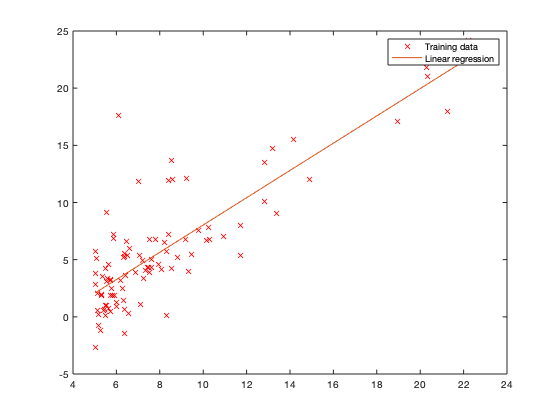


% Plot the linear fit
plot(x(:,2),y,'rx')
hold on
plot(x(:,2),x*theta)
legend('Training data', 'Linear regression')
hold off 

### Varying alpha and number of iterations

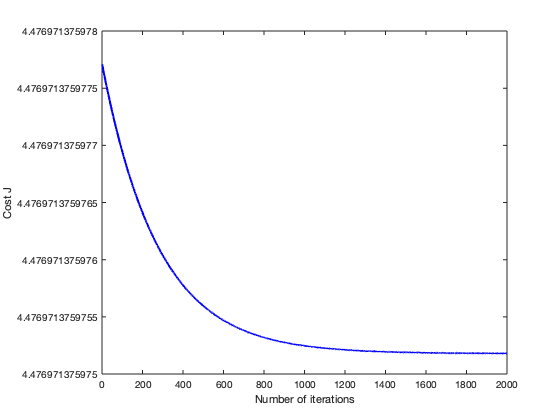

% Run gradient descent:
% Choose some alpha value
alpha = 0.01;
num_iters = 2000;

% Init Theta and Run Gradient Descent 

[~, J_history] = gradientDescent(x, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters,J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868



predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


### Visualizing $J(\theta)$

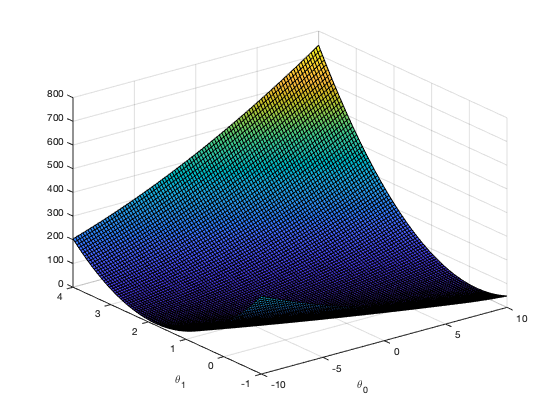

% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);
% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(x, y, t);
    end
end


% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

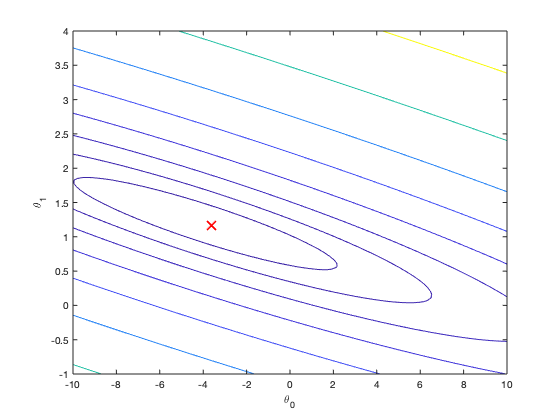


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

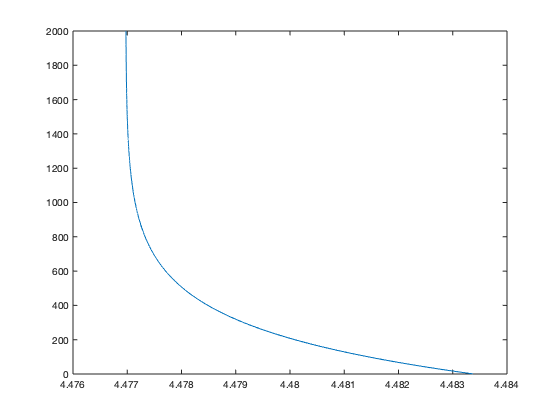

figure;
plot(J_history, 1:num_iters);

# Linear Regression with multiple variables

### Loading the dataset

Housing_Price=importfile('ex1data2.txt');
x1=(Housing_Price.Size_of_House);
x2=(Housing_Price.No_of_bedrooms);
y=Housing_Price.Price;
m = length(y);

### Feature Normalization

[x1,mu1,sigma1]=featureNormalize(x1);
[x2,mu2,sigma2]=featureNormalize(x2);
x0=ones(size(x1,1),1);
X=[x0 x1 x2];

### Computing Cost

theta=zeros(3,1);
computeCostMulti(X,y,theta)

ans = 6.5592e+10

### Gradient Descent

% Run gradient descent
% Choose some alpha value
alpha = 0.6;
num_iters = 400;
theta = zeros(3, 1); 

% Init Theta and Run Gradient Descent 

[theta, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);
J_history

J_history = 	1.0e+10 *

    1.2157
    0.3975
    0.2527
    0.2217
    0.2124
    0.2085
    0.2066
    0.2056
    0.2050
    0.2047


fprintf('Minimum cost computed from gradient descent:\n%f',min(J_history))

Minimum cost computed from gradient descent:
2043280050.602827

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
340412.659574,
110631.050279

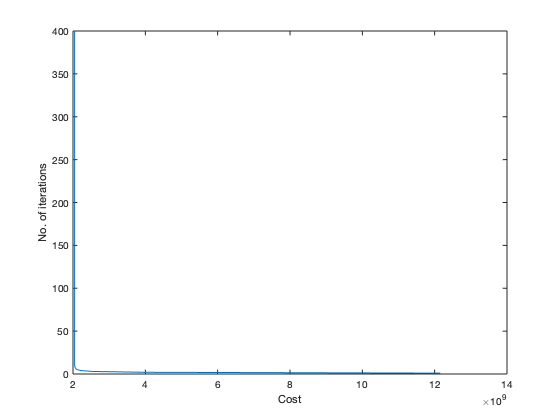

figure;
plot(J_history, 1:num_iters);
ylabel("No. of iterations")
xlabel("Cost")

val=(1650-mu1)/sigma1;
price = [theta(1)+theta(2)*val];

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $291594.141933

## Normal Equation

X_normal=X;
theta_normal=normalEqn(X_normal,y);

fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta_normal(1),theta_normal(2),theta_normal(3));

Theta computed from the normal equations:
340412.659574
110631.050279
-6649.474271

J=computeCostMulti(X,y,theta_normal)

J = 2.0433e+09